# LEVITATORE MAGNETICO

E' un sistema non lineare il cui scopo è di tenere in sospensione una massa; nel caso analizzato, quest'ultima è di forma sferica. 

Le forze che agiscono su di essa sono:

- forza di gravità $m_s g$ costante e diretta verso il basso;

- forza magnetica $F_m$, diretta verso l'alto, il cui modulo è direttamente proporzionale alla corrente che scorre nell'elettromagnete, ed inversamente proporzionale al quadrato della posizione $z$ della massa.

Esistono infinite coppie di punti $(I_{m0},z_{0})$ per cui $F_m=m_s g$, ossia per cui il sistema è in equilibrio. Tuttavia, questo è un equilibrio instabile, in quanto se si perturba di poco lo stato del sistema, questo si allontana definitivamente dalla posizione di equilibrio.

## Caratterizzazione e linearizzazione del sistema fisico

Per controllare il sistema con le tecniche note, è necessario linearizzare le equazioni che lo descrivono attorno ad uno dei punti di equilibrio, così da ricavare un modello detto di *prima approssimazione*. In particolare, si sceglie come $z_0$ la posizione della massa per cui la tensione del trasduttore di posizione è pari a $V_{trasd}=0V$, e in corrispondenza di questa si misura la $I_{m0}$ mediante l'uscita *current sense*.

- TRASDUTTORE DI POSIZIONE

Il dispositivo è stato caratterizzato misurando la tensione $V_{trasd}$ in corrispondenza di diverse posizioni $z$ assunte dalla massa, lette sulla scala graduata. In generale, si può scrivere la seguente relazione: $\left\lbrack \begin{array}{c}
z_{k+i} -z_0 \\
\ldotp \ldotp \ldotp \\
z_{k+N} -z_0 
\end{array}\right\rbrack K_{\text{trasd}} =\left\lbrack \begin{array}{c}
V_{k+i} \\
\ldotp \ldotp \ldotp \\
V_{k+N} 
\end{array}\right\rbrack$. Dunque scegliendo un opportuno intervallo in cui la caratteristica è lineare, che si traduce nella scelta di opportuni valori di k ed N, si ottiene il valore del guadagno del trasduttore di posizione.

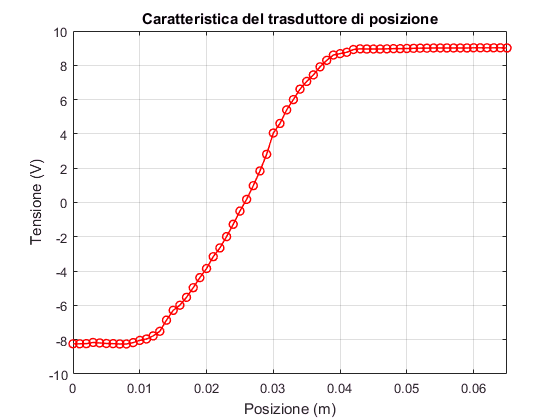

clear variables
close all
clc

m=0.022; %in kg
g=9.81;
z0=0.06; %Utilizzando la scala graduata
z0_ref=0.02; %Rispetto all'origine del sistema di riferimento
Im0=0.6596; %Corrente nell'elettromagnete all'equilibrio
Kc=2.5; %Guadagno del convertitore corrente/tensione
K_trans=1/Kc; %Guadagno dell'amplificatore di transconduttanza
Var=load('V_transducer_correct.mat');
Var.Position1=(Var.Position1-4)*0.01; %Posizione da cm a m
figure();
plot(Var.Position1,Var.Voltage1,'rO-','Linewidth',1.1);
grid on;
xlabel('Posizione (m)');
ylabel('Tensione (V)');
axis([0.00 0.065 -10 10]);
title('Caratteristica del trasduttore di posizione');

V_trasd=(Var.Voltage1(31)-Var.Voltage1(21))/0.01 %#ok<*NOPTS> 

V_trasd =    790


- COSTANTE ELETTROMECCANICA

Per la seconda legge della dinamica, possiamo scrivere in generale che: $m_s \ddot{z} \left(t\right)=m_s g-K_M \frac{I_m^2 }{z^2 }$. Tuttavia, mediante il compensatore interno, possiamo porci in condizioni di equilibrio, per cui $\ddot{z}(t)=0$, e calcolare quindi l'unica incognita, $K_M$, registrando, in diverse condizioni di equilibrio, i valori dei trasduttori di posizioni e di corrente. In particolare, avendo già ricavato la caratteristica che lega $V_{trasd}$ a $z$, si piò invertire quest'ultima per trovare i valori di posizione corrispondenti.

Eln=load('Elettromagnete_1.mat');
z=interp1(Var.Voltage1(11:44),Var.Position1(11:44),Eln.Km_dati(:,1)); %inversione della caratteristica posizione-tensione
Km=((Eln.Km_dati(:,2)).^2./((z).^2))\(m*g*(ones(26,1)))

Km =      3.181216907222571e-04


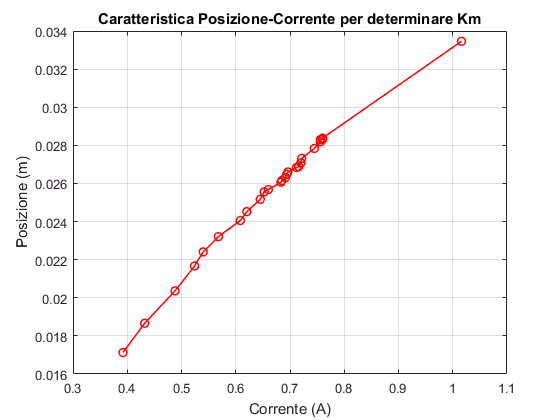

figure();
plot(Eln.Km_dati(:,2),z,'ro-','Linewidth',1.1); grid on;
xlabel('Corrente (A)');
ylabel('Posizione (m)');
title('Caratteristica Posizione-Corrente per determinare Km');

- DETERMINAZIONE DELLA FUNZIONE DI TRASFERIMENTO

Si ricava la funzione di trasferimento del sistema fisico con i parametri appena calcolati:

Im0_calc=z0_ref*sqrt(m*g/Km);
A=[0 1;((2*g)/(Im0))*sqrt(m*g/Km) 0];
B=[0;-2*g*K_trans/Im0];
C=[V_trasd 0];
D=0;
sys=ss(A,B,C,D)


sys =
 
  A = 
          x1     x2
   x1      0      1
   x2  774.8      0
 
  B = 
          u1
   x1      0
   x2  -11.9
 
  C = 
        x1   x2
   y1  790    0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



G=zpk(tf(sys))


G =
 
        -9399.5
  -------------------
  (s-27.83) (s+27.83)
 
Continuous-time zero/pole/gain model.



## Design del controllore: analisi della stabilità del sistema retroazionato e progetto a regime

Il progetto è realizzato mediante la tecnica del loopshaping.

Specifiche:

- Tempo di salita della risposta al gradino: $t_s$$\le$$15ms$;

- Sovraelongazione della risposta al gradino: $\hat{s}$$\le$$30\%$;

- Errore stazionario di inseguimento di un riferimento a gradino: $e_{st}$$=0$;

- Sfasamento temporale a regime nella risposta alla rampa unitaria, $t_r\le 20ms$;

Per soddisfare i requisiti sugli errori di inseguimento a regime, è, in entrambi i casi, necessario un sistema di tipo 1, per cui il controllore a regime avrà funzione di trasferimento: $C_{\mathrm{ss}} \left(s\right)=\frac{K_C }{s}$. Tuttavia, laddove il primo non impone scelte particolari sul modulo di $K_C$, il secondo richiede la ricerca di un limite inferiore per tale parametro, determinato mediante iol teorema del valore finale.

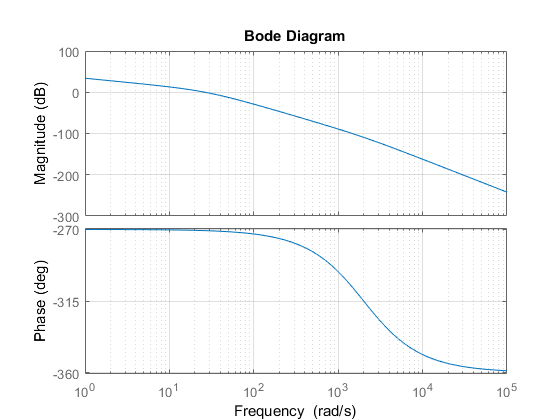

s=tf('s');
Ts=1e-3; %Periodo di campionamento
G1=G;
ZOH=1/(1+s*Ts*0.5);
G_ZOH=G1*ZOH;

%Steady-state
Kc=4.12; 
Css=-Kc/s;
Lss=Css*G_ZOH; %fdt della catena ad anello aperto
figure(); bode(Lss), grid on;

Number of poles in RHP of open-loop system: 1
Number of net encirclements around the -1 point:   1
=> Number of poles in RHP of closed-loop system:   2
=> Closed-loop-system is unstable


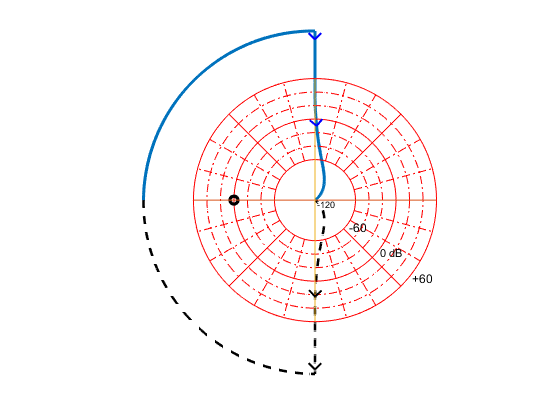

nyqlog(Lss) 

(L'implementazione della funzione *nyqlog* si trova seguendo il link: [MathWorks-Nyqlog](http:// https://it.mathworks.com/matlabcentral/fileexchange/7444-nyquist-plot-with-logarithmic-amplitudes)).

Come si evince dall'applicazione del criterio di Nyquist, il solo controllore a regime non dà origine ad un sistema retroazionato stabile. Tuttavia, si nota anche che, con la scelta adoperata per il segno di $K_C$, è possibile stabilizzare il sitema con l'introduzione di un anticipo di fase.

## Design del controllore: transitorio

Oltre all'incremento di fase necessario a stabilizzare il sistema, per rispettare i requisiti di sovraelongazione e tempo di salita, è necessario che la funzione di trasferimento della catena ad anello aperto sia fuori dai luoghi delle radici indicati in figura, il cui valore è stato ricavato con un metodo grafico, e che abbia una frequenza di crossover $w_{c,des}\ge120$$rad/s$.

Tp=mag2db(1.38);
Sp=mag2db(1.65);
wc_des=120;
figure(); nichols(Lss,'k'); hold on; t_grid(Tp); s_grid(Sp);

L'anticipo di fase necessario a stabilizzare il sistema, e a portarlo fuori dai luoghi delle radici è di circa $150^{\circ}$, ed è stato implementato utilizzando uno zero reale negativo, che recupera circa $90^\circ$, e successivamente, una *lead network* che recupera i restanti $60^{\circ}$.

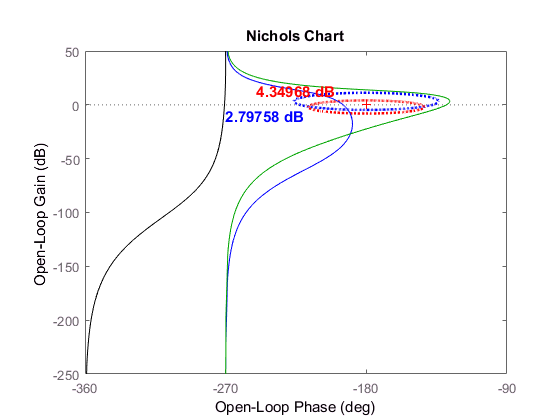

wn=10;
wz=wc_des/wn;
Cz=(1+s/wz);
C0=Css*Cz;
L1=C0*G_ZOH;
hold on; nichols(L1,'b');
md=18;
wn=6;
wd=wc_des/wn;
Cd=(1+s/wd)/(1+s/(md*wd));
C0_def=C0*Cd;
L2=C0_def*G_ZOH;
hold on; nichols(L2,'g');

La funzione di trasferimento a tempo discreto del controllore progettato è quindi:

Cd=c2d(C0_def,Ts,'tustin')


Cd =
 
  -5.321 z^2 + 10.47 z - 5.154
  ----------------------------
     z^2 - 1.695 z + 0.6949
 
Sample time: 0.001 seconds
Discrete-time transfer function.



che stabilizza sicuramente il sistema retroazionato, come si evince dall'applicazione del criterio di Nyquist.

Number of poles in RHP of open-loop system: 1
Number of net encirclements around the -1 point:   -1
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


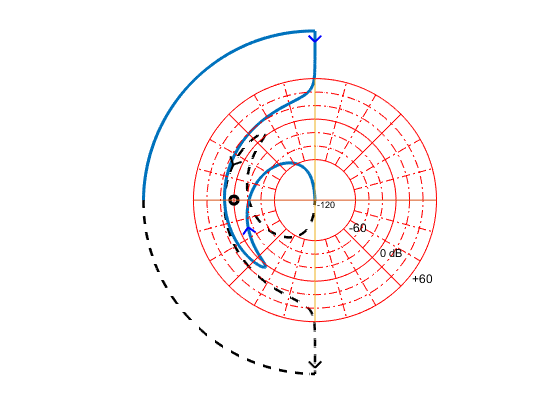

figure(); nyqlog(L2)

## Simulazione sul modello lineare

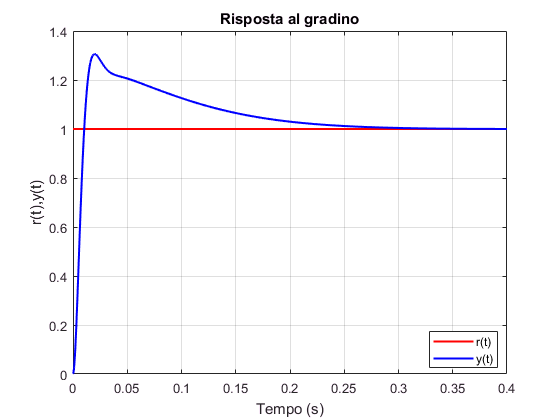

r_s=1;
rho=1;
rho_ramp=0;
t_stop=0.4;
min_step=1e-5;
max_step=1e-3;
sim('Levitatore_lin');
figure();
plot(r.time,r.data,'r','Linewidth',1.5);
hold on;
plot(y.time,y.data,'b','Linewidth',1.5);
title('Risposta al gradino'); xlabel('Tempo (s)'); ylabel ('r(t),y(t)'); legend('r(t)','y(t)','Location','best'); grid on;

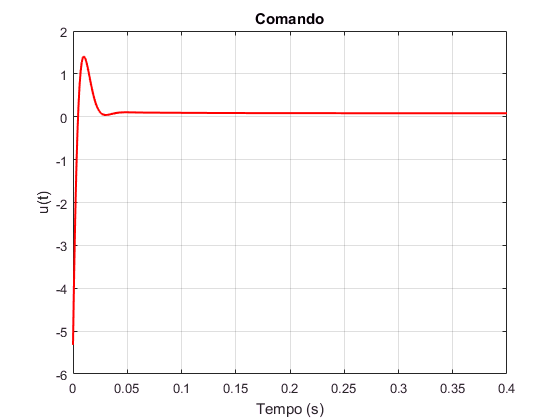

figure();
plot(u.time,u.data,'r','Linewidth',1.5); title('Comando'); xlabel('Tempo (s)'); ylabel('u(t)'); grid on;

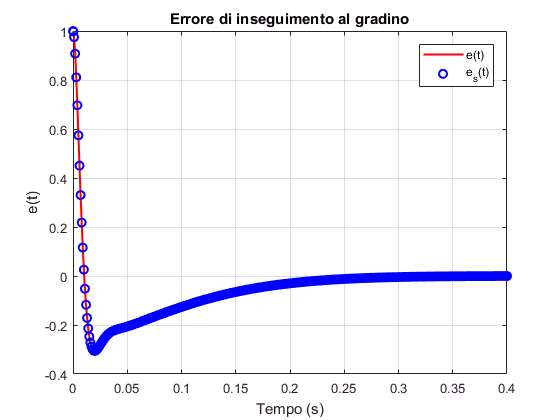

figure();
plot(e.time,e.data,'r','Linewidth',1.5); hold on; plot(e.time,e.data,'bo','Linewidth',1.5); title('Errore di inseguimento al gradino'); xlabel('Tempo (s)'); ylabel('e(t)'); grid on;
legend('e(t)','e_s(t)');

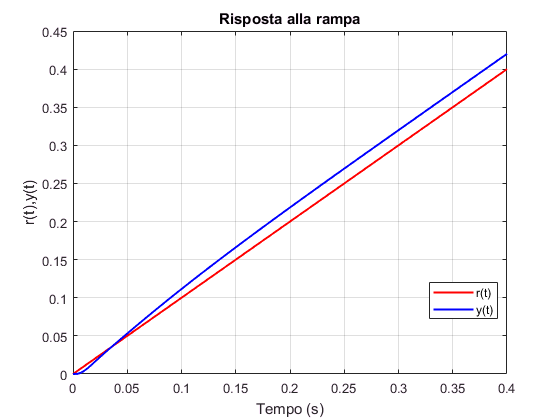

r_s=-1;
rho=0;
rho_ramp=1;
sim('Levitatore_lin');
figure();
plot(r.time,r.data,'r','Linewidth',1.5);
hold on;
plot(y.time,y.data,'b','Linewidth',1.5);
title('Risposta alla rampa'); xlabel('Tempo (s)'); ylabel('r(t),y(t)'); legend('r(t)','y(t)','Location','best'); grid on;

**Risultati ottenuti**

- $\hat{s}\approx 30.6\%$;

- $t_s =10.34 ms$;

- $|e^\infty _s (t)|=0$, con $r(t)=\epsilon(t)$;

- 
$$t_r=20ms$$
, con $r(t)=t\epsilon (t)$.

Come si può notare, il requisito sulla sovraelongazione non è stato esattamente rispettato: a tal proposito, si sarebbe potuta implementare la rete anticipatrice con un doppio zero a frequenza coincidente, e successivamente aggiungere un polo di chiusura per rendere proprio il sitema. Effettivamente, in questo modo si otteneva $\hat{s}\approx25\%$, ma il comando u(t) aveva un'ampiezza massima in valore assoluto troppo alta, che mandava in saturazione il sistema fisico, per cui si è preferito optare per la soluzione qui riportata.

Si nota, inoltre, che il tempo di assestamento è molto grande. Questa specifica potrebbe essere migliorata con l'utilizzo di una $\omega_c$ più grande, ma anche questa scelta aumenterebbe notevolmente l'ampiezza massima del comando.

## Simulazione sul sitema reale

Essendo il sistema fisico non lineare, ci si aspetta in generale un peggioramento delle specifiche.

- RISPOSTA ALL'ONDA QUADRA: $f=1Hz$, $duty-cycle=50\%$, $A=100mV_{pp}$.

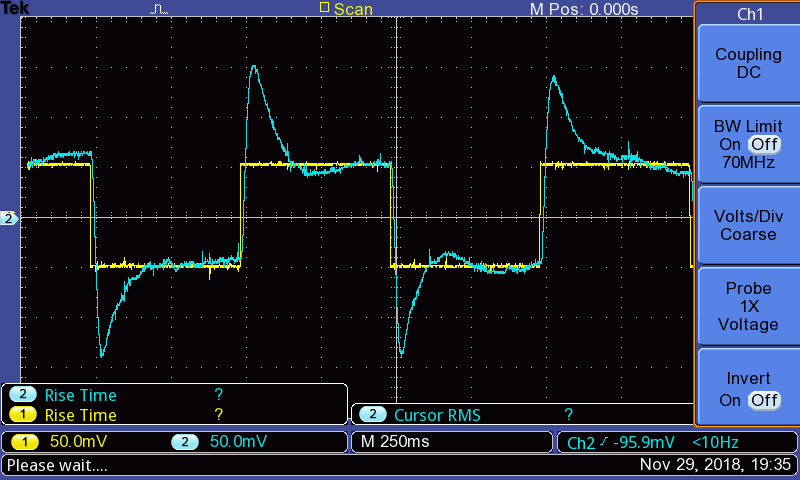

       Si nota che il requisito sulla sovrelongazione massima non è soddisfatto se si utilizza il controllore sul sistema reale, e che quindi si conferma che una migliore implementazione preveda un recupero di fase quanto più ampio possibile, ma ciò andrebbe ad aumentare drasticamente l'ampiezza massima del comando.

        Il tempo di salita risulta invece essere $t_r \approx 25ms$, non esattamente rispettato, ma comunque ragionevolmente in linea con le specifiche.

- COMANDO

Con un'onda quadra in input a frequenza $f=1Hz$, $duty-cycle=50\%$, $A=200mV_{pp}$ si ottiene:

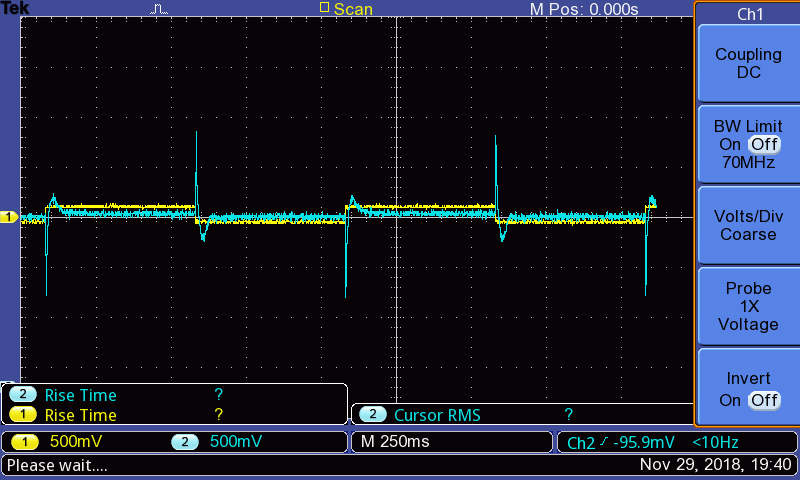

            come si nota, l'ampiezza massima è pari a circa 1V, e quando l'ampiezza del riferimento aumenta, si ottiene un comportamento analogo. Poiché il sistema fisico accetta un comando compreso tra 0 e 10V (la parte negativa può essere ottenuta aggiungendo un offset), ed essendo la risposta circa simmetrica, considerando che, come si evince anche dalla simulazione, $max\{u(t)\}\approx 5max\{r(t)\}$, la "dinamica d'ingresso" del sistema controllato in questo modo è pari a $max\{r(t)\}\approx\pm 1V_{pp}$.

## CONSIDERAZIONI FINALI

Con questa esperienza si nota come, in generale, un progetto "teorico" di un sistema di controllo sia molto distante dall'implementazione su un sistema fisico reale, di cui bisogna tenere in considerazione le specifiche proprie. In questo caso, a causa del requisito stringente sull'ampiezza massima del comando, è necessario accettare una sovraelongazione e un tempo di assestamento peggiori, che, nel caso specifico, non sono tuttavia critici.

Un altro parametro importante, sempre legato ad $u(t)$, è la massima ampiezza del riferimento che garantisce una corretta operazione dell'attuatore, che ho chiamato precedentemente "dinamica d'ingresso". Anche in questo caso, poiché, aumentare la dinamica vuol dire ridurre l'ampiezza massima del comando, ciò si traduce inevitabilmente in un transitorio pù lungo, e con una sovraelongazione più alta.